# Diagram of signal processing  

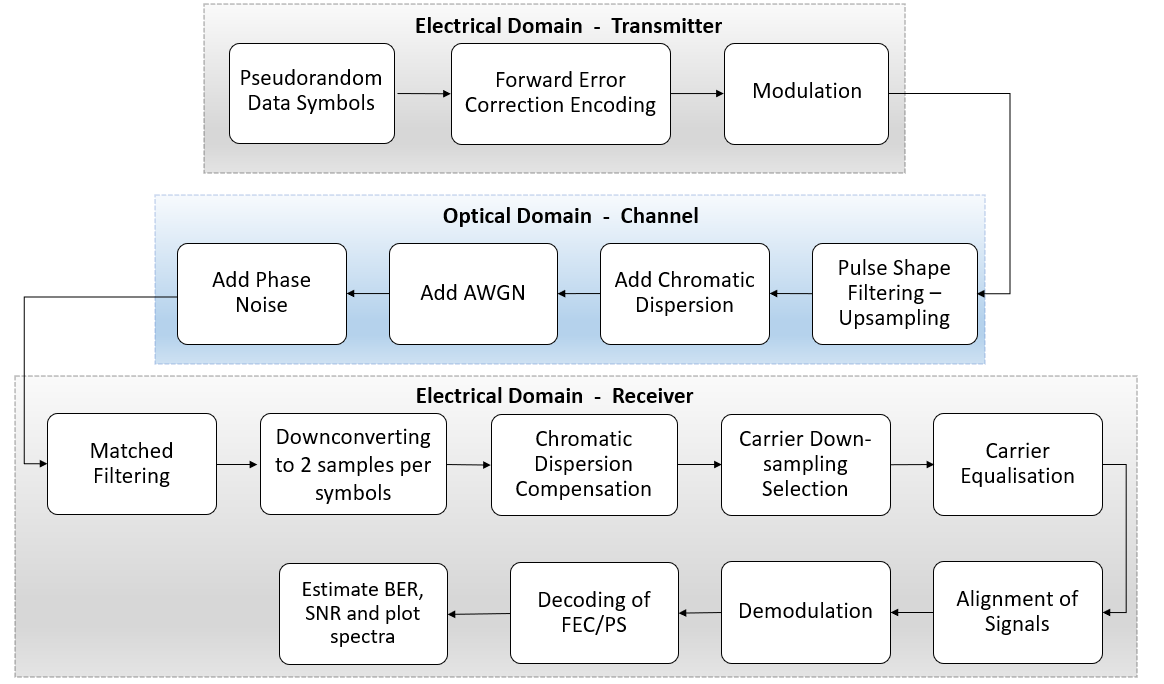

## Constants and Initial Conditions

clearvars;
tic
%Resetting the rng seed
%rng("default");
%rng(1960);

purple = [0.75,0,0.75];

enable_FEC = false;

enable_pulse_shaping = true;
enable_downsampling = true;
enable_alignment = true;

enable_AWGN = true;
enable_phase_noise = false;
enable_chromatic_dispersion = true; %This should only be done in tandem to pulse shaping
enable_adaptive_eq = true;

enable_frequency_equal = false; %No implementation
enable_carrier_equal = false;
enable_plots = true;

% Need coupling component implemented
% Need Non-linearities tested and introduced


num_symbols = 32*1024;
symbol_rate = 50e9;
time_step = 1/symbol_rate;
linewidth = 20;
variance = 2*pi*linewidth*time_step;

%Modulation Orders
M1 = 2;
M2 = 4;
M3 = 16;
M4 = 64;

%Bits/Symbol
k1 = log2(M1);
k2 = log2(M2);
k3 = log2(M3);
k4 = log2(M4);

%Transmitted Bits
b_bits = k1*num_symbols;
q_bits = k2*num_symbols;
qam16_bits = k3*num_symbols;
qam64_bits = k4*num_symbols;

## Forward Error Correction

if enable_FEC
    
    LDPC = dvbs2ldpc(3/4);
    encLDPC = comm.LDPCEncoder(LDPC); %#ok<*UNRCH>
    
    % K: uncoded message length
    % N: coded message length
    LDPC_K = size(LDPC,2)-size(LDPC,1);
    LDPC_N = size(LDPC,2);
    
    symbols_bi = randi([0 M1-1],num_symbols,1);
    
    %% nK-by-1 column vector of binary data where K = (3/4)*64800 = 48600n
    padding = (floor(length(symbols_bi)/LDPC_K)+1)*LDPC_K-length(symbols_bi);
    
    padding = padding/2; %Halve for adding to both sides
    
    symbols_b = reshape(padarray(symbols_bi,padding,"both"),LDPC_K,[]);
    
    if(length(symbols_b)~=LDPC_K)
        error("Incorrect dimension for encoding");
    end
    
    %BPSK Encoding
    
    symbols_temp = nan(LDPC_N,size(symbols_b,2));
    
    for i=1:size(symbols_b,2)
        symbols_temp(:,i) = encLDPC(symbols_b(:,i));
    end
    symbols_b = reshape(symbols_temp,1,[]);
    
    %QPSK Encoding
    %LDPCs only take binary inputs, will have to convert symbols to bits, encode,
    %convert to symbols again,  and for decoding, symbols to bits, decode,
    %bits to symbols.
    
    symbols_qi = randi([0 M2-1],num_symbols,1);
    symbols_q = conversion(encLDPC,symbols_qi,M2,LDPC_K,LDPC_N);
    
    %QAM16 Encoding
    %LDPCs only take binary inputs, will have to convert symbols to bits, encode,
    %convert to symbols again,  and for decoding, symbols to bits, decode,
    %bits to symbols.
    
    symbols_16i = randi([0 M3-1],num_symbols,1);
    symbols_16 = conversion(encLDPC,symbols_16i,M3,LDPC_K,LDPC_N);
    
    
    symbols_64i = randi([0 M4-1],num_symbols,1);
    symbols_64 = conversion(encLDPC,symbols_64i,M4,LDPC_K,LDPC_N);
    
end

## Modulation

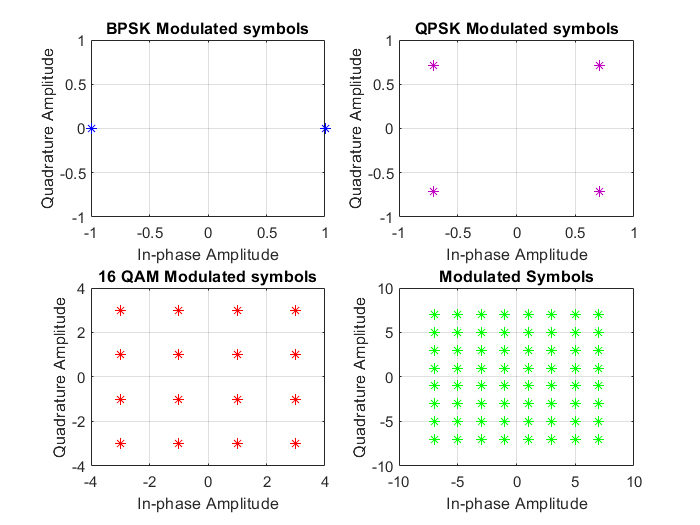

%BPSK
if (~enable_FEC)
    symbols_b = randi([0 M1-1],1,num_symbols);
end
bpsk_mod = pskmod(symbols_b,M1,0,'gray');


%QPSK
if (~enable_FEC)
    symbols_q = randi([0 M2-1],1,num_symbols);
end
qpsk_mod = pskmod(symbols_q,M2,pi/M2,'gray');


%16QAM
if (~enable_FEC)
    symbols_16 = randi([0 M3-1],1,num_symbols);
end
qam16_mod = qammod(symbols_16,M3,'gray');


%64QAM
if (~enable_FEC)
    symbols_64 = randi([0 M4-1],1,num_symbols);
end
qam64_mod = qammod(symbols_64,M4,'gray');

if enable_plots
    figure
    subplot(2,2,1,gca);
    plot(bpsk_mod,'*','MarkerEdgeColor','blue','MarkerFaceColor',"blue");
    title("BPSK Modulated symbols");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    xlim([-1,1]);
    ylim([-1,1]);
    grid on;
    subplot(2,2,2);
    grid on;
    plot(qpsk_mod,'*','MarkerEdgeColor',purple,'MarkerFaceColor',purple);
    title("QPSK Modulated symbols");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    grid on;
    subplot(2,2,3);
    plot(qam16_mod,'*','MarkerEdgeColor','red','MarkerFaceColor',"red");
    title("16 QAM Modulated symbols");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    grid on;
    subplot(2,2,4);
    plot(qam64_mod,'*','MarkerEdgeColor','green','MarkerFaceColor',"green");
    title("64 QAM Modulated symbols");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    title("Modulated Symbols");
    grid on;
end

# **Transition into the Optical Domain (TX)**

## Pulse Shaping and Upconverting

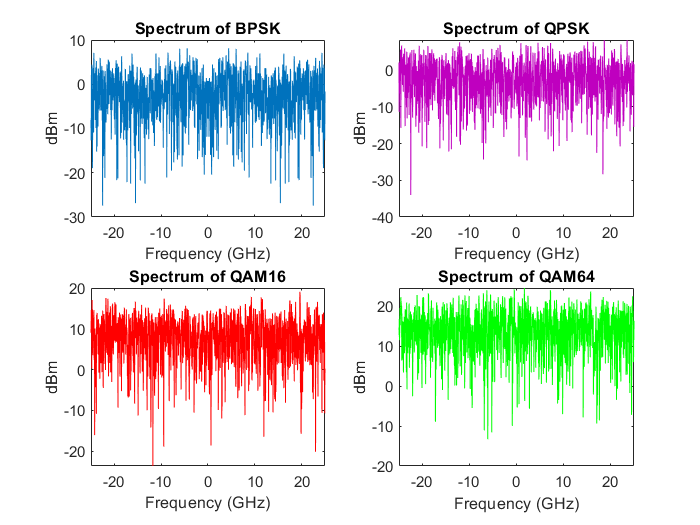

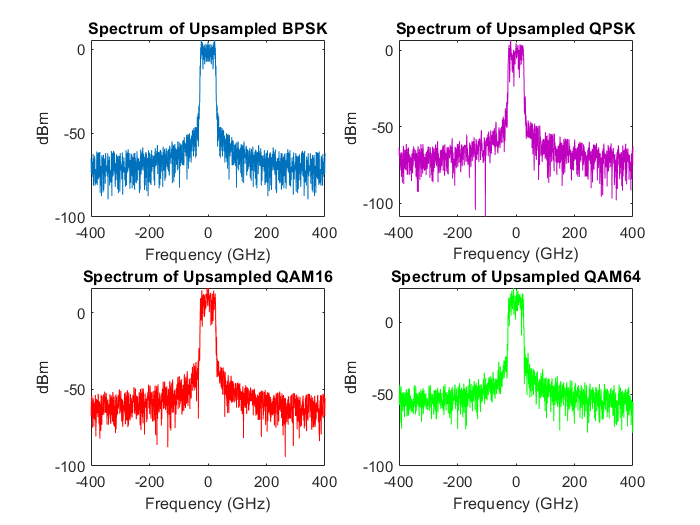

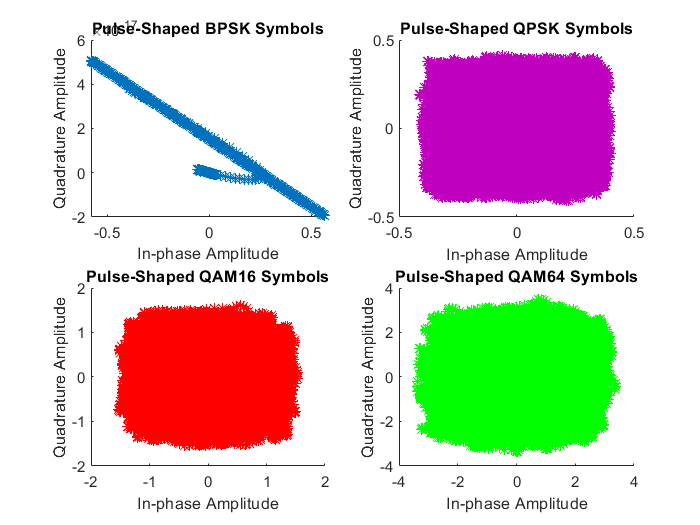

    span = 20;
    upsampling = 16;
    Rolloff = 0.1;
    receiver_samples_per_symbol = 2; 
    correl = true;
    
if enable_pulse_shaping
    
    
    
    %Define Filter Constants
    
    %These might not be defined correctly
    optical_sample_rate = symbol_rate*upsampling;
    num_optical_samples = num_symbols*upsampling;
    receiver_sample_rate = receiver_samples_per_symbol*symbol_rate;
    num_samples = num_symbols*receiver_samples_per_symbol;
    %Define Filter Objects
    
    tx_ps_filter = comm.RaisedCosineTransmitFilter("FilterSpanInSymbols",span,"OutputSamplesPerSymbol",upsampling,"RolloffFactor",Rolloff,"Shape","Square root","Gain",1);
    rx_ps_filter = comm.RaisedCosineReceiveFilter("FilterSpanInSymbols",span,"InputSamplesPerSymbol",upsampling,"DecimationFactor",upsampling/receiver_samples_per_symbol,"RolloffFactor",Rolloff,"Shape","Square root","Gain",1);
    
 %% Filter Delays as defined in example sent (usage unclear)
    % filtDelay_b = k1*span;
    % filtDelay_q = k2*span;
    % filtDelay_qam16 = k3*span;
    % filtDelay_qam64 = k4*span;
    
    %Inspect Filters
    
    if enable_plots
        %fvtool(tx_ps_filter);
        filter_taps = coeffs(tx_ps_filter);
        filter_taps = filter_taps.Numerator;
        
        raised_cosine_scope = dsp.SpectrumAnalyzer('SampleRate',optical_sample_rate);
        hide(raised_cosine_scope);
        matched_scope = dsp.SpectrumAnalyzer("SampleRate",symbol_rate);
        hide(matched_scope);
        
        
        figure
        
        subplot(2,2,1,gca);
        matched_scope(bpsk_mod.');
        data = getSpectrumData(matched_scope);
        plot(data.FrequencyVector{:}/1e9,data.Spectrum{:});
        title("Spectrum of BPSK");
        xlabel("Frequency (GHz)");
        ylabel("dBm");
        
        subplot(2,2,2);
        matched_scope(qpsk_mod.');
        data = getSpectrumData(matched_scope);
        plot(data.FrequencyVector{:}/1e9,data.Spectrum{:},'Color',purple);
        title("Spectrum of QPSK");
        xlabel("Frequency (GHz)");
        ylabel("dBm");
        
        subplot(2,2,3);
        matched_scope(qam16_mod.');
        data = getSpectrumData(matched_scope);
        plot(data.FrequencyVector{:}/1e9,data.Spectrum{:},'Color','red');
        title("Spectrum of QAM16");
        xlabel("Frequency (GHz)");
        ylabel("dBm");
        
        subplot(2,2,4);
        matched_scope(qam64_mod.');
        data = getSpectrumData(matched_scope);
        plot(data.FrequencyVector{:}/1e9,data.Spectrum{:},'Color','green');
        title("Spectrum of QAM64");
        xlabel("Frequency (GHz)");
        ylabel("dBm");
        
    end
    
     
    if correl
        corr_bpsk = bpsk_mod;
        corr_qpsk = qpsk_mod;
        corr_qam16 = qam16_mod;
        corr_qam64 = qam64_mod;
    end
    
    
    %Filter Transmitted Signals
    bpsk_mod = tx_ps_filter(bpsk_mod.').';
    qpsk_mod = tx_ps_filter(qpsk_mod.').';
    qam16_mod = tx_ps_filter(qam16_mod.').';
    qam64_mod = tx_ps_filter(qam64_mod.').';
    
    if enable_plots
        
        figure
        subplot(2,2,1,gca);
        raised_cosine_scope(bpsk_mod.');
        data = getSpectrumData(raised_cosine_scope);
        plot(data.FrequencyVector{:}/1e9,data.Spectrum{:});
        title("Spectrum of Upsampled BPSK");
        xlabel("Frequency (GHz)");
        ylabel("dBm");
        
        subplot(2,2,2);
        raised_cosine_scope(qpsk_mod.');
        data = getSpectrumData(raised_cosine_scope);
        plot(data.FrequencyVector{:}/1e9,data.Spectrum{:},'Color',purple);
        title("Spectrum of Upsampled QPSK");
        xlabel("Frequency (GHz)");
        ylabel("dBm");
        
        subplot(2,2,3);
        raised_cosine_scope(qam16_mod.');
        data = getSpectrumData(raised_cosine_scope);
        plot(data.FrequencyVector{:}/1e9,data.Spectrum{:},'Color','red');
        title("Spectrum of Upsampled QAM16");
        xlabel("Frequency (GHz)");
        ylabel("dBm");
        
        subplot(2,2,4);
        raised_cosine_scope(qam64_mod.');
        data = getSpectrumData(raised_cosine_scope);
        plot(data.FrequencyVector{:}/1e9,data.Spectrum{:},'Color','green');
        title("Spectrum of Upsampled QAM64");
        xlabel("Frequency (GHz)");
        ylabel("dBm");
        
        figure
        subplot(2,2,1,gca);
        scatter(real(bpsk_mod),imag(bpsk_mod),'*');
        title("Pulse-Shaped BPSK Symbols");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,2);
        scatter(real(qpsk_mod),imag(qpsk_mod),'*','MarkerEdgeColor',purple,'MarkerFaceColor',purple);
        title("Pulse-Shaped QPSK Symbols");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,3);
        scatter(real(qam16_mod),imag(qam16_mod),'*','MarkerEdgeColor','red','MarkerFaceColor','red');
        title("Pulse-Shaped QAM16 Symbols");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,4);
        scatter(real(qam64_mod),imag(qam64_mod),'*','MarkerEdgeColor','green','MarkerFaceColor','green');
        title("Pulse-Shaped QAM64 Symbols");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        
        %     figure
        %     eyediagram(bpsk_mod(1,1:1024),upscaling);
        %     eyediagram(qpsk_mod(1,1:1024),upscaling);
        %     eyediagram(qam16_mod(1,1:1024),upscaling);
        
    end
    
else
    [optical_sample_rate,receiver_sample_rate] = deal(symbol_rate);
end

## Chromatic Dispersion

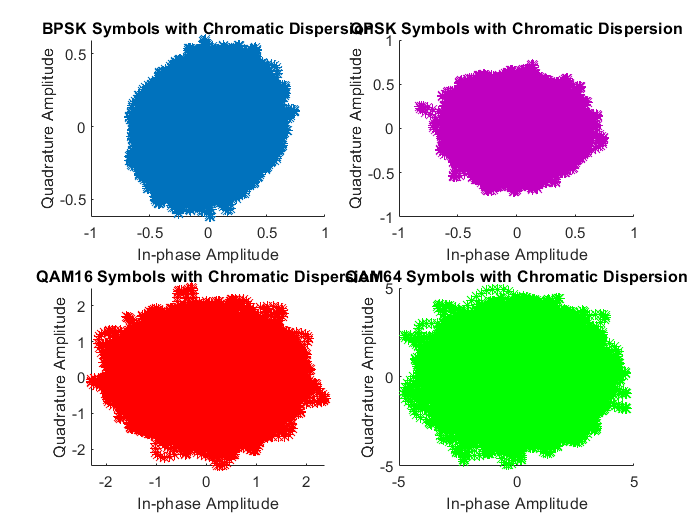

if enable_chromatic_dispersion
    
    D = 17*1e-6; %/s/m/m
    lambda = 1550e-9;
    z = 40e3;
    
    %For LMS Filter
    lms_bpsk = bpsk_mod;
    lms_qpsk = qpsk_mod;
    lms_qam16 = qam16_mod;
    lms_qam64 = qam64_mod;
    
    
    bpsk_mod = Chromatic_Dispersion(bpsk_mod,num_symbols,symbol_rate,D,z,lambda);
    qpsk_mod = Chromatic_Dispersion(qpsk_mod,num_symbols,symbol_rate,D,z,lambda);
    qam16_mod = Chromatic_Dispersion(qam16_mod,num_symbols,symbol_rate,D,z,lambda);
    qam64_mod = Chromatic_Dispersion(qam64_mod,num_symbols,symbol_rate,D,z,lambda);
    
    
    if enable_plots
        figure
        subplot(2,2,1,gca);
        scatter(real(bpsk_mod),imag(bpsk_mod),'*');
        title("BPSK Symbols with Chromatic Dispersion");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,2);
        scatter(real(qpsk_mod),imag(qpsk_mod),'*','MarkerEdgeColor',purple,'MarkerFaceColor',purple);
        title("QPSK Symbols with Chromatic Dispersion");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,3);
        scatter(real(qam16_mod),imag(qam16_mod),'*','MarkerEdgeColor','red','MarkerFaceColor','red');
        title("QAM16 Symbols with Chromatic Dispersion");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,4);
        scatter(real(qam64_mod),imag(qam64_mod),'*','MarkerEdgeColor','green','MarkerFaceColor','green');
        title("QAM64 Symbols with Chromatic Dispersion");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
    end
    
end

## AWGN

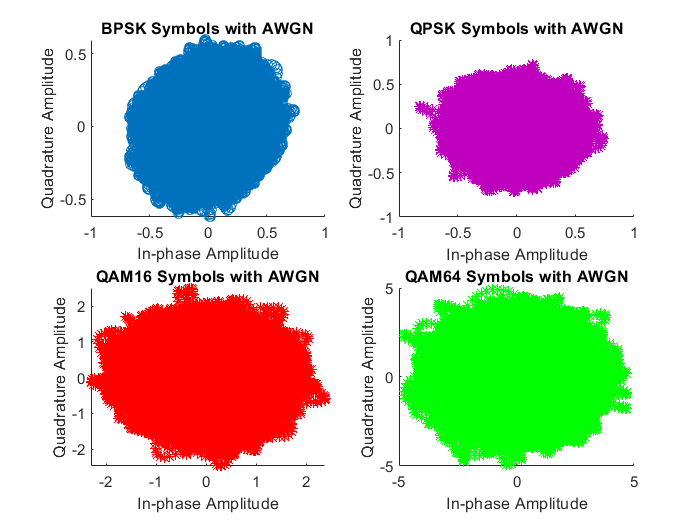

if enable_AWGN
    
    %AWGN with an SNR of 20dB (10,15,20,25,30,35,40)
    
    %SNR = Eb/No + 10log10(k) - 10log10(upsampling) 
    % To update properly in the future
    
    SNR_b = 40;
    SNR_q = 40;
    SNR_16 = 40;
    SNR_64 = 40;
    
    
    bpsk_mod = awgn(bpsk_mod,SNR_b,"measured");
    qpsk_mod = awgn(qpsk_mod,SNR_q,"measured");
    qam16_mod = awgn(qam16_mod,SNR_16,"measured");
    qam64_mod = awgn(qam64_mod,SNR_64,"measured");
    
    
    %Plots
    if enable_plots
        figure
        subplot(2,2,1,gca);
        scatter(real(bpsk_mod),imag(bpsk_mod));
        title("BPSK Symbols with AWGN");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,2);
        scatter(real(qpsk_mod),imag(qpsk_mod),'*','MarkerEdgeColor',purple,'MarkerFaceColor',purple);
        title("QPSK Symbols with AWGN");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,3);
        scatter(real(qam16_mod),imag(qam16_mod),'*','MarkerEdgeColor','red','MarkerFaceColor','red');
        title("QAM16 Symbols with AWGN");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,4);
        scatter(real(qam64_mod),imag(qam64_mod),'*','MarkerEdgeColor','green','MarkerFaceColor','green');
        title("QAM64 Symbols with AWGN");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
    end
    
end

## Phase Noise

if enable_phase_noise
    
    %Generate Phase Noise
    rng(1960);
    num_sam = num_samples;
    
    if num_sam ~= length(bpsk_mod)   
        num_sam = length(bpsk_mod); 
    end
    
    phase_noise = randn(1,num_sam);
    
    random_walk_phase_noise = cumsum(sqrt(variance)*phase_noise);
    
    t = (1:num_sam)*time_step*1e9; %in nanoseconds
    
    %Can try mixing phase noise with awgn noise to set its SNR
    
    %Apply Phase Noise
    
    bpsk_mod = bpsk_mod.*exp(1j*random_walk_phase_noise);
    qpsk_mod = qpsk_mod.*exp(1j*random_walk_phase_noise);
    qam16_mod = qam16_mod.*exp(1j*random_walk_phase_noise);
    qam64_mod = qam64_mod.*exp(1j*random_walk_phase_noise);
    
    
    if enable_plots
        figure
        plot(t,random_walk_phase_noise,t,filtfilt(ones(100,1)/100,1,random_walk_phase_noise));
        title('Phase noise over time with \Delta\lambda= 100 kHz');
        xlabel("time (ns)");
        ylabel("Phase (rads)");
        legend("phase noise","smoothed phase noise");
        
        figure
        subplot(2,2,1,gca);
        scatter(real(bpsk_mod),imag(bpsk_mod));
        title("BPSK Symbols with Phase Noise");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,2);
        scatter(real(qpsk_mod),imag(qpsk_mod),'*','MarkerEdgeColor',purple,'MarkerFaceColor',purple);
        title("QPSK Symbols with Phase Noise");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,3);
        scatter(real(qam16_mod),imag(qam16_mod),'*','MarkerEdgeColor','red','MarkerFaceColor','red');
        title("QAM16 Symbols with Phase Noise");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,4);
        scatter(real(qam64_mod),imag(qam64_mod),'*','MarkerEdgeColor','green','MarkerFaceColor','green');
        title("QAM64 Symbols with Phase Noise");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
    end
end

# **Transition into Electrical Domain (RX)**

## Matched Filter and Downconverting

if enable_pulse_shaping
         
     bpsk_mod = rx_ps_filter(bpsk_mod.').';
     qpsk_mod = rx_ps_filter(qpsk_mod.').';
     qam16_mod = rx_ps_filter(qam16_mod.').';
     qam64_mod = rx_ps_filter(qam64_mod.').';
     
end      

## **Inverse Chromatic Dispersion Model**

% if enable_chromatic_dispersion && enable_inv_cd
%         
%         %2*symbol_rate accounts for the downsampling and the 2 samples/symbol
%         
%         bpsk_mod = Inv_of_Chromatic_Dispersion(bpsk_mod,receiver_sample_rate,D,z,lambda);
%         qpsk_mod = Inv_of_Chromatic_Dispersion(qpsk_mod,receiver_sample_rate,D,z,lambda);
%         qam16_mod = Inv_of_Chromatic_Dispersion(qam16_mod,receiver_sample_rate,D,z,lambda);
%         qam64_mod = Inv_of_Chromatic_Dispersion(qam64_mod,receiver_sample_rate,D,z,lambda);
%         
%         
%         if enable_plots
%             figure
%             subplot(2,2,1,gca);
%             scatter(real(bpsk_mod),imag(bpsk_mod),'*');
%             title("BPSK Symbols with Chromatic Dispersion Inverted");
%             xlabel("In-phase Amplitude");
%             ylabel("Quadrature Amplitude");
%             subplot(2,2,2);
%             scatter(real(qpsk_mod),imag(qpsk_mod),'*','MarkerEdgeColor',purple,'MarkerFaceColor',purple);
%             title("QPSK Symbols with Chromatic Dispersion Inverted");
%             xlabel("In-phase Amplitude");
%             ylabel("Quadrature Amplitude");
%             subplot(2,2,3);
%             scatter(real(qam16_mod),imag(qam16_mod),'*','MarkerEdgeColor','red','MarkerFaceColor','red');
%             title("QAM16 Symbols with Chromatic Dispersion Inverted");
%             xlabel("In-phase Amplitude");
%             ylabel("Quadrature Amplitude");
%             subplot(2,2,4);
%             scatter(real(qam64_mod),imag(qam64_mod),'*','MarkerEdgeColor','green','MarkerFaceColor','green');
%             title("QAM64 Symbols with Chromatic Dispersion Inverted");
%             xlabel("In-phase Amplitude");
%             ylabel("Quadrature Amplitude");
%         end
% end

## Chromatic Dispersion Compensation

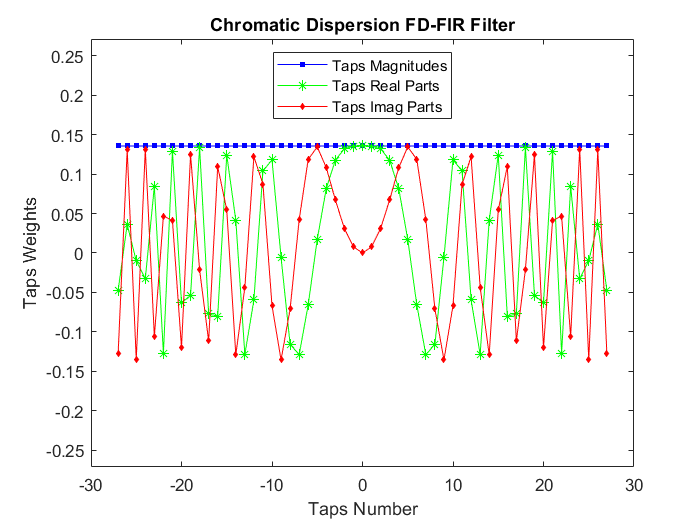

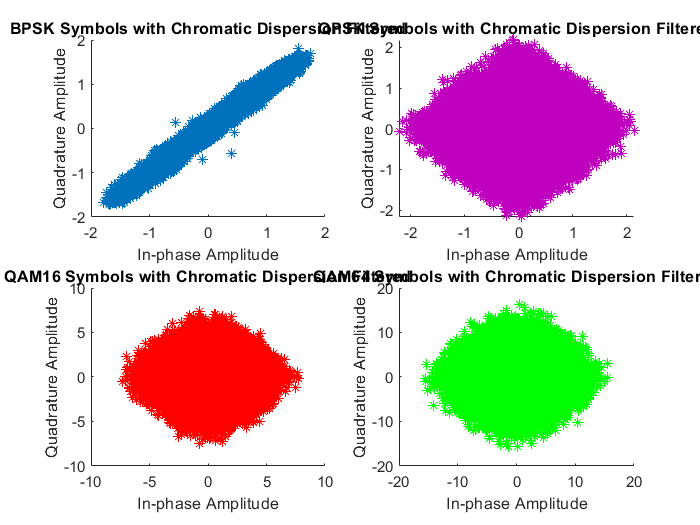

if enable_chromatic_dispersion
    %if (~enable_inv_cd)
        FD = true;
        OLS = false;
        
        
        if FD
            
            %Basic Chromatic Dispersion Filter
            CD_FD_FIR = CD_Filter(symbol_rate,D,z,lambda);
            l_tap = length(CD_FD_FIR);
            
            if enable_plots
                realfilt = real(CD_FD_FIR);
                imagfilt = imag(CD_FD_FIR);
                magfilt = abs(CD_FD_FIR);
                k = (-floor(length(CD_FD_FIR)/2):floor(length(CD_FD_FIR)/2));
                %fvtool(CD_FD_FIR);
                figure
                plot(k,magfilt,"blue","Marker","square","MarkerFaceColor","blue","MarkerSize",3);
                hold on
                plot(k,realfilt,"green","Marker","*");
                plot(k,imagfilt,"red","Marker","diamond","MarkerFaceColor","red","MarkerSize",3);
                title("Chromatic Dispersion FD-FIR Filter");
                xlabel("Taps Number");
                ylabel("Taps Weights");
                ylim([-2*magfilt(1) 2*magfilt(1)]);
                legend("Taps Magnitudes","Taps Real Parts","Taps Imag Parts","Location","north");
            end
        end
        
        if OLS
            
            OLS_FIR = OLS_filter(receiver_sample_rate,D,z,lambda);
            l_tap = length(OLS_FIR);
            
            if enable_plots
                realfilt = real(OLS_FIR);
                imagfilt = imag(OLS_FIR);
                magfilt = abs(OLS_FIR);
                k = (-floor(length(OLS_FIR)/2):floor(length(OLS_FIR)/2));
                %fvtool(OLS_FIR);
                figure
                plot(k,magfilt,"blue","Marker","square","MarkerFaceColor","blue","MarkerSize",3);
                hold on
                plot(k,realfilt,"green","Marker","*");
                plot(k,imagfilt,"red","Marker","diamond","MarkerFaceColor","red","MarkerSize",3);
                title("Chromatic Dispersion OLS-FIR Filter");
                xlabel("Taps Number");
                ylabel("Taps Weights");
                ylim([-2*max(magfilt) 2*max(magfilt)]);
                legend("Taps Magnitudes","Taps Real Parts","Taps Imag Parts","Location","north");
            end
            
        end
        
        %Filter signals to remove CD [Confusion between Filter(), and FFTfilt()]
        
        if FD
            
            %overlap-and-add
            bpsk_mod = fftfilt(CD_FD_FIR,bpsk_mod);
            qpsk_mod = fftfilt(CD_FD_FIR,qpsk_mod);
            qam16_mod = fftfilt(CD_FD_FIR,qam16_mod);
            qam64_mod = fftfilt(CD_FD_FIR,qam64_mod);
            
            
            %Overlap-and-save
            %fdf = dsp.FrequencyDomainFIRFilter("Numerator",CD_FD_FIR,"NumeratorDomain","Time","Method","Overlap-save");
            
            %bpsk_mod = fdf(bpsk_mod.').';
            %qpsk_mod = fdf(qpsk_mod.').';
            %qam16_mod = fdf(qam16_mod.').';
            %qam64_mod = fdf(qam64_mod.').';
            
            
        elseif OLS
            bpsk_mod = fftfilt(OLS_FIR,bpsk_mod);
            qpsk_mod = fftfilt(OLS_FIR,qpsk_mod);
            qam16_mod = fftfilt(OLS_FIR,qam16_mod);
            qam64_mod = fftfilt(OLS_FIR,qam64_mod); %,2^(ceil(log2(l_tap))+1) for FFT length 
            
        else
            %LMS Filter (Unsure how to implement)
                 lms = dsp.LMSFilter();
                 [lms_bpsk,~,~] = lms(bpsk_mod.',lms_bpsk.');
                 [lms_qpsk,~,~] = lms(qpsk_mod.',lms_qpsk.');
                 [lms_qam16,~,~] = lms(qam16_mod.',lms_qam16.');
                 [lms_qam64,lms_error,lms_weights] = lms(qam64_mod.',lms_qam64.');
            
                 bpsk_mod = lms_bpsk.';
                 qpsk_mod = lms_qpsk.';
                 qam16_mod = lms_qam16.';
                 qam64_mod = lms_qam64.';
        end
        
        if enable_plots
            figure
            subplot(2,2,1,gca);
            scatter(real(bpsk_mod),imag(bpsk_mod),'*');
            title("BPSK Symbols with Chromatic Dispersion Filtered");
            xlabel("In-phase Amplitude");
            ylabel("Quadrature Amplitude");
            subplot(2,2,2);
            scatter(real(qpsk_mod),imag(qpsk_mod),'*','MarkerEdgeColor',purple,'MarkerFaceColor',purple);
            title("QPSK Symbols with Chromatic Dispersion Filtered");
            xlabel("In-phase Amplitude");
            ylabel("Quadrature Amplitude");
            subplot(2,2,3);
            scatter(real(qam16_mod),imag(qam16_mod),'*','MarkerEdgeColor','red','MarkerFaceColor','red');
            title("QAM16 Symbols with Chromatic Dispersion Filtered");
            xlabel("In-phase Amplitude");
            ylabel("Quadrature Amplitude");
            subplot(2,2,4);
            scatter(real(qam64_mod),imag(qam64_mod),'*','MarkerEdgeColor','green','MarkerFaceColor','green');
            title("QAM64 Symbols with Chromatic Dispersion Filtered");
            xlabel("In-phase Amplitude");
            ylabel("Quadrature Amplitude");
        end
    %end
end

## Adaptive Equalisation (CMA Algorithm)

if enable_adaptive_eq
    
    x = qpsk_mod.'; %Received Input
    
    h_taps = 17; 
    mu = 0.01; % Step Size
    
    h = zeros(h_taps,1);
    u = zeros(h_taps,1);
    
    h(floor(h_taps/2)+1) = 1;  
    length_after_eq = length(x)/receiver_samples_per_symbol;
    
    y = zeros([length_after_eq 1],'like', x);
    e = zeros([length_after_eq 1],'like', x);

    for i = 1:length_after_eq
        
         for j = h_taps:-1:receiver_samples_per_symbol+1
            u(j) = u(j-receiver_samples_per_symbol);
         end    
    
         for k=1:receiver_samples_per_symbol
            u(k,1) = x((i-1)*receiver_samples_per_symbol+k,1);
         end
        
        %Filter 
        
        ytemp = h' * u; % We need the complex transpose in this case
        
        etemp = (1 - abs(ytemp).^2);
        
        if etemp>1e-5
            mu = 0.011;
        else
            mu = 0.0022;
        end
        
        etemp = ytemp*etemp;
        
        
        h = h + mu*u*conj(etemp);
        
        y(i,1) = ytemp;
        
        e(i,1) = etemp;
        
    end    
    
    if enable_plots
        figure
        hold on
        scatter(real(qpsk_mod),imag(qpsk_mod));
        scatter(real(y),imag(y));
        legend("Noisy Data","Filtered Data");
        title("QPSK symbols before and after Adaptive Filtering");
        ylabel("Quadrature Amplitude");
        xlabel("In-phase Amplitude");
    end
    
%     for i =  training_size+1 : num_samples
%         
%     	temp = x(i:-1:i-h_taps+1) ;
%         
%         y(i) = h' * temp ;
%         
%         e(i) = 1 - abs(y(i))^2;
%     end
%     
        if enable_plots
            figure
            scatter(real(y),imag(y));
            title("Adaptive Filtered Data");
            ylabel("Quadrature Amplitude");
            xlabel("In-phase Amplitude");
            
            figure
            semilogy((abs(e))) ;
            title('Error curve');
            
            figure
            plot(abs(h),'bo-');
            title("Filter Weights");
            xlabel("Weight Index");
            ylabel("Weight Magnitude");
        end
    
    qpsk_mod = y.';
    
    
end

i = 24

i = 29

i = 33

i = 35

i = 37

i = 41

i = 42

i = 43

i = 45

i = 46

i = 50

i = 52

i = 55

i = 57

i = 59

i = 61

i = 63

i = 64

i = 65

i = 68

i = 71

i = 72

i = 76

i = 78

i = 81

i = 83

i = 84

i = 89

i = 93

i = 95

i = 99

i = 102

i = 104

i = 105

i = 107

i = 110

i = 111

i = 112

i = 115

i = 117

i = 122

i = 125

i = 131

i = 134

i = 136

i = 138

i = 139

i = 143

i = 144

i = 146

i = 149

i = 150

i = 152

i = 154

i = 156

i = 160

i = 168

i = 170

i = 174

i = 176

i = 178

i = 181

i = 183

i = 187

i = 190

i = 193

i = 194

i = 198

i = 199

i = 201

i = 203

i = 205

i = 209

i = 214

i = 218

i = 221

i = 227

i = 228

i = 232

i = 235

i = 238

i = 241

i = 242

i = 243

i = 248

i = 249

i = 251

i = 253

i = 256

i = 258

i = 259

i = 260

i = 264

i = 266

i = 269

i = 272

i = 273

i = 276

i = 278

i = 280

i = 284

i = 285

i = 287

i = 288

i = 291

i = 294

i = 297

i = 308

i = 311

i = 312

i = 314

i = 316

i = 317

i = 318

i = 319

i = 323

i = 325

i = 327

i = 330

i = 334

i = 335

i = 339

i = 341

i = 342

i = 343

i = 346

i = 351

i = 357

i = 358

i = 360

i = 361

i = 363

i = 364

i = 367

i = 368

i = 372

i = 373

i = 375

i = 376

i = 379

i = 381

i = 382

i = 384

i = 386

i = 388

i = 389

i = 391

i = 393

i = 394

i = 398

i = 400

i = 402

i = 404

i = 406

i = 407

i = 411

i = 414

i = 418

i = 420

i = 421

i = 425

i = 433

i = 436

i = 439

i = 442

i = 446

i = 448

i = 453

i = 454

i = 455

i = 457

i = 459

i = 460

i = 464

i = 466

i = 467

i = 469

i = 474

i = 477

i = 479

i = 485

i = 486

i = 488

i = 491

i = 494

i = 495

i = 498

i = 501

i = 506

i = 508

i = 509

i = 511

i = 512

i = 513

i = 515

i = 516

i = 517

i = 518

i = 520

i = 521

i = 522

i = 523

i = 524

i = 526

i = 529

i = 530

i = 531

i = 532

i = 533

i = 534

i = 538

i = 539

i = 540

i = 543

i = 546

i = 547

i = 548

i = 549

i = 551

i = 553

i = 554

i = 556

i = 559

i = 560

i = 561

i = 562

i = 563

i = 568

i = 570

i = 571

i = 574

i = 577

i = 582

i = 584

i = 586

i = 588

i = 589

i = 590

i = 595

i = 596

i = 597

i = 598

i = 600

i = 606

i = 609

i = 610

i = 611

i = 614

i = 615

i = 616

i = 617

i = 620

i = 621

i = 623

i = 624

i = 625

i = 626

i = 627

i = 629

i = 630

i = 631

i = 633

i = 635

i = 636

i = 637

i = 639

i = 640

i = 641

i = 642

i = 643

i = 645

i = 648

i = 653

i = 654

i = 656

i = 658

i = 659

i = 662

i = 664

i = 665

i = 666

i = 668

i = 672

i = 673

i = 676

i = 677

i = 678

i = 681

i = 684

i = 685

i = 688

i = 690

i = 691

i = 692

i = 693

i = 695

i = 697

i = 698

i = 699

i = 701

i = 702

i = 703

i = 704

i = 707

i = 708

i = 710

i = 711

i = 712

i = 714

i = 716

i = 717

i = 718

i = 719

i = 720

i = 722

i = 723

i = 724

i = 726

i = 727

i = 728

i = 729

i = 730

i = 732

i = 735

i = 737

i = 738

i = 739

i = 741

i = 742

i = 743

i = 745

i = 746

i = 747

i = 748

i = 750

i = 751

i = 752

i = 753

i = 754

i = 755

i = 756

i = 758

i = 759

i = 761

i = 763

i = 764

i = 765

i = 769

i = 770

i = 773

i = 774

i = 775

i = 777

i = 778

i = 779

i = 780

i = 783

i = 786

i = 787

i = 790

i = 793

i = 794

i = 795

i = 797

i = 800

i = 804

i = 805

i = 806

i = 807

i = 809

i = 810

i = 813

i = 814

i = 816

i = 817

i = 818

i = 822

i = 824

i = 825

i = 826

i = 827

i = 828

i = 830

i = 832

i = 833

i = 834

i = 835

i = 836

i = 837

i = 838

i = 839

i = 840

i = 841

i = 842

i = 843

i = 847

i = 848

i = 849

i = 850

i = 851

i = 853

i = 854

i = 855

i = 856

i = 857

i = 858

i = 860

i = 861

i = 863

i = 864

i = 865

i = 868

i = 869

i = 871

i = 872

i = 873

i = 875

i = 876

i = 877

i = 879

i = 880

i = 885

i = 886

i = 888

i = 889

i = 890

i = 891

i = 896

i = 897

i = 898

i = 900

i = 901

i = 902

i = 903

i = 904

i = 907

i = 908

i = 910

i = 911

i = 912

i = 914

i = 915

i = 916

i = 919

i = 920

i = 921

i = 922

i = 924

i = 928

i = 929

i = 930

i = 932

i = 933

i = 934

i = 936

i = 938

i = 939

i = 941

i = 942

i = 945

i = 946

i = 947

i = 948

i = 950

i = 961

i = 962

i = 963

i = 965

i = 966

i = 969

i = 973

i = 974

i = 975

i = 976

i = 977

i = 978

i = 979

i = 980

i = 983

i = 984

i = 988

i = 989

i = 991

i = 995

i = 996

i = 998

i = 1000

i = 1002

i = 1003

i = 1004

i = 1005

i = 1006

i = 1008

i = 1009

i = 1011

i = 1012

i = 1014

i = 1015

i = 1018

i = 1023

i = 1024

i = 1027

i = 1029

i = 1030

i = 1031

i = 1032

i = 1033

i = 1035

i = 1036

i = 1039

i = 1040

i = 1041

i = 1042

i = 1043

i = 1044

i = 1046

i = 1047

i = 1048

i = 1049

i = 1051

i = 1052

i = 1053

i = 1055

i = 1058

i = 1059

i = 1060

i = 1062

i = 1063

i = 1064

i = 1066

i = 1067

i = 1068

i = 1069

i = 1070

i = 1071

i = 1072

i = 1073

i = 1075

i = 1078

i = 1079

i = 1082

i = 1084

i = 1085

i = 1086

i = 1087

i = 1088

i = 1089

i = 1091

i = 1092

i = 1093

i = 1094

i = 1095

i = 1097

i = 1099

i = 1100

i = 1101

i = 1103

i = 1104

i = 1105

i = 1106

i = 1107

i = 1110

i = 1111

i = 1112

i = 1113

i = 1114

i = 1117

i = 1118

i = 1119

i = 1120

i = 1121

i = 1122

i = 1123

i = 1124

i = 1126

i = 1127

i = 1128

i = 1129

i = 1130

i = 1132

i = 1137

i = 1138

i = 1139

i = 1140

i = 1142

i = 1145

i = 1146

i = 1147

i = 1149

i = 1150

i = 1151

i = 1155

i = 1156

i = 1157

i = 1158

i = 1160

i = 1161

i = 1162

i = 1163

i = 1165

i = 1167

i = 1169

i = 1170

i = 1171

i = 1172

i = 1173

i = 1174

i = 1175

i = 1176

i = 1177

i = 1178

i = 1180

i = 1185

i = 1186

i = 1187

i = 1190

i = 1192

i = 1193

i = 1194

i = 1195

i = 1196

i = 1197

i = 1198

i = 1199

i = 1200

i = 1201

i = 1202

i = 1205

i = 1206

i = 1207

i = 1208

i = 1209

i = 1210

i = 1211

i = 1212

i = 1213

i = 1214

i = 1216

i = 1218

i = 1219

i = 1221

i = 1222

i = 1223

i = 1225

i = 1226

i = 1227

i = 1228

i = 1230

i = 1233

i = 1235

i = 1237

i = 1238

i = 1239

i = 1240

i = 1242

i = 1243

i = 1244

i = 1245

i = 1246

i = 1247

i = 1248

i = 1251

i = 1252

i = 1255

i = 1257

i = 1258

i = 1262

i = 1263

i = 1265

i = 1266

i = 1267

i = 1269

i = 1270

i = 1272

i = 1275

i = 1277

i = 1279

i = 1280

i = 1281

i = 1283

i = 1284

i = 1287

i = 1288

i = 1290

i = 1291

i = 1292

i = 1293

i = 1295

i = 1298

i = 1299

i = 1301

i = 1302

i = 1304

i = 1305

i = 1306

i = 1307

i = 1308

i = 1309

i = 1310

i = 1311

i = 1316

i = 1317

i = 1318

i = 1319

i = 1324

i = 1326

i = 1327

i = 1328

i = 1330

i = 1331

i = 1333

i = 1335

i = 1337

i = 1338

i = 1339

i = 1340

i = 1342

i = 1343

i = 1344

i = 1346

i = 1348

i = 1352

i = 1353

i = 1354

i = 1355

i = 1358

i = 1360

i = 1361

i = 1362

i = 1363

i = 1364

i = 1365

i = 1369

i = 1370

i = 1371

i = 1372

i = 1373

i = 1374

i = 1375

i = 1376

i = 1379

i = 1380

i = 1381

i = 1382

i = 1383

i = 1386

i = 1387

i = 1388

i = 1389

i = 1390

i = 1392

i = 1394

i = 1395

i = 1396

i = 1400

i = 1401

i = 1402

i = 1404

i = 1405

i = 1412

i = 1415

i = 1417

i = 1418

i = 1419

i = 1420

i = 1421

i = 1424

i = 1425

i = 1430

i = 1431

i = 1432

i = 1433

i = 1434

i = 1435

i = 1436

i = 1437

i = 1438

i = 1439

i = 1440

i = 1441

i = 1442

i = 1443

i = 1447

i = 1448

i = 1450

i = 1451

i = 1452

i = 1453

i = 1454

i = 1455

i = 1456

i = 1457

i = 1458

i = 1460

i = 1462

i = 1465

i = 1467

i = 1468

i = 1469

i = 1470

i = 1472

i = 1473

i = 1474

i = 1475

i = 1476

i = 1477

i = 1478

i = 1480

i = 1481

i = 1482

i = 1483

i = 1484

i = 1485

i = 1487

i = 1488

i = 1489

i = 1491

i = 1494

i = 1495

i = 1497

i = 1499

i = 1500

i = 1501

i = 1504

i = 1505

i = 1506

i = 1507

i = 1508

i = 1510

i = 1513

i = 1515

i = 1516

i = 1519

i = 1521

i = 1523

i = 1524

i = 1525

i = 1526

i = 1527

i = 1529

i = 1530

i = 1532

i = 1533

i = 1534

i = 1535

i = 1536

i = 1537

i = 1543

i = 1544

i = 1546

i = 1548

i = 1550

i = 1551

i = 1552

i = 1553

i = 1554

i = 1555

i = 1556

i = 1557

i = 1559

i = 1561

i = 1562

i = 1563

i = 1564

i = 1565

i = 1569

i = 1570

i = 1571

i = 1572

i = 1573

i = 1574

i = 1575

i = 1576

i = 1577

i = 1578

i = 1579

i = 1580

i = 1581

i = 1582

i = 1583

i = 1584

i = 1585

i = 1586

i = 1588

i = 1589

i = 1590

i = 1591

i = 1592

i = 1596

i = 1598

i = 1599

i = 1601

i = 1602

i = 1603

i = 1604

i = 1605

i = 1606

i = 1607

i = 1608

i = 1611

i = 1613

i = 1614

i = 1616

i = 1617

i = 1619

i = 1620

i = 1621

i = 1622

i = 1624

i = 1626

i = 1627

i = 1632

i = 1634

i = 1636

i = 1637

i = 1638

i = 1639

i = 1640

i = 1641

i = 1644

i = 1645

i = 1647

i = 1650

i = 1651

i = 1652

i = 1654

i = 1656

i = 1658

i = 1660

i = 1662

i = 1663

i = 1667

i = 1668

i = 1669

i = 1670

i = 1671

i = 1672

i = 1673

i = 1674

i = 1676

i = 1677

i = 1678

i = 1680

i = 1682

i = 1684

i = 1686

i = 1688

i = 1689

i = 1690

i = 1691

i = 1695

i = 1696

i = 1697

i = 1698

i = 1700

i = 1705

i = 1707

i = 1711

i = 1712

i = 1714

i = 1715

i = 1716

i = 1717

i = 1719

i = 1720

i = 1721

i = 1722

i = 1723

i = 1727

i = 1728

i = 1729

i = 1730

i = 1732

i = 1733

i = 1734

i = 1736

i = 1739

i = 1740

i = 1741

i = 1742

i = 1743

i = 1745

i = 1746

i = 1747

i = 1748

i = 1750

i = 1751

i = 1752

i = 1755

i = 1756

i = 1757

i = 1758

i = 1759

i = 1760

i = 1763

i = 1764

i = 1766

i = 1768

i = 1769

i = 1771

i = 1773

i = 1774

i = 1775

i = 1776

i = 1777

i = 1779

i = 1780

i = 1782

i = 1783

i = 1786

i = 1787

i = 1788

i = 1789

i = 1791

i = 1793

i = 1794

i = 1795

i = 1796

i = 1797

i = 1799

i = 1800

i = 1801

i = 1803

i = 1805

i = 1806

i = 1808

i = 1809

i = 1810

i = 1811

i = 1817

i = 1818

i = 1819

i = 1820

i = 1821

i = 1822

i = 1823

i = 1824

i = 1826

i = 1827

i = 1829

i = 1830

i = 1831

i = 1832

i = 1833

i = 1834

i = 1835

i = 1836

i = 1837

i = 1838

i = 1841

i = 1843

i = 1845

i = 1847

i = 1848

i = 1849

i = 1850

i = 1853

i = 1854

i = 1855

i = 1856

i = 1857

i = 1859

i = 1860

i = 1861

i = 1862

i = 1863

i = 1866

i = 1867

i = 1868

i = 1869

i = 1870

i = 1871

i = 1872

i = 1873

i = 1874

i = 1875

i = 1876

i = 1879

i = 1881

i = 1882

i = 1883

i = 1885

i = 1887

i = 1889

i = 1890

i = 1893

i = 1894

i = 1895

i = 1898

i = 1899

i = 1900

i = 1901

i = 1905

i = 1906

i = 1907

i = 1908

i = 1911

i = 1913

i = 1915

i = 1916

i = 1917

i = 1918

i = 1919

i = 1920

i = 1921

i = 1922

i = 1923

i = 1924

i = 1925

i = 1927

i = 1930

i = 1931

i = 1932

i = 1934

i = 1936

i = 1937

i = 1938

i = 1940

i = 1942

i = 1944

i = 1945

i = 1946

i = 1948

i = 1949

i = 1950

i = 1952

i = 1953

i = 1954

i = 1955

i = 1958

i = 1962

i = 1963

i = 1964

i = 1965

i = 1966

i = 1968

i = 1969

i = 1970

i = 1973

i = 1974

i = 1976

i = 1977

i = 1978

i = 1980

i = 1981

i = 1983

i = 1984

i = 1986

i = 1987

i = 1989

i = 1990

i = 1991

i = 1992

i = 1993

i = 1994

i = 1995

i = 1996

i = 1999

i = 2000

i = 2001

i = 2003

i = 2005

i = 2006

i = 2007

i = 2008

i = 2009

i = 2010

i = 2011

i = 2012

i = 2013

i = 2014

i = 2015

i = 2016

i = 2018

i = 2019

i = 2020

i = 2021

i = 2023

i = 2024

i = 2025

i = 2026

i = 2027

i = 2029

i = 2030

i = 2031

i = 2033

i = 2035

i = 2037

i = 2039

i = 2041

i = 2042

i = 2044

i = 2045

i = 2047

i = 2049

i = 2051

i = 2052

i = 2053

i = 2054

i = 2055

i = 2057

i = 2060

i = 2063

i = 2065

i = 2066

i = 2067

i = 2069

i = 2070

i = 2071

i = 2072

i = 2073

i = 2074

i = 2076

i = 2079

i = 2080

i = 2081

i = 2082

i = 2084

i = 2086

i = 2087

i = 2089

i = 2092

i = 2093

i = 2094

i = 2096

i = 2097

i = 2098

i = 2099

i = 2100

i = 2102

i = 2106

i = 2109

i = 2110

i = 2112

i = 2115

i = 2116

i = 2117

i = 2119

i = 2125

i = 2126

i = 2127

i = 2128

i = 2129

i = 2133

i = 2134

i = 2135

i = 2136

i = 2137

i = 2138

i = 2139

i = 2141

i = 2143

i = 2144

i = 2145

i = 2146

i = 2150

i = 2151

i = 2152

i = 2154

i = 2155

i = 2156

i = 2157

i = 2159

i = 2160

i = 2161

i = 2162

i = 2166

i = 2167

i = 2168

i = 2169

i = 2172

i = 2174

i = 2176

i = 2177

i = 2178

i = 2182

i = 2185

i = 2186

i = 2187

i = 2188

i = 2190

i = 2191

i = 2193

i = 2194

i = 2196

i = 2197

i = 2198

i = 2199

i = 2200

i = 2201

i = 2203

i = 2204

i = 2206

i = 2207

i = 2210

i = 2212

i = 2213

i = 2214

i = 2217

i = 2219

i = 2221

i = 2223

i = 2224

i = 2225

i = 2227

i = 2228

i = 2229

i = 2230

i = 2233

i = 2236

i = 2237

i = 2240

i = 2241

i = 2244

i = 2245

i = 2246

i = 2247

i = 2248

i = 2249

i = 2250

i = 2252

i = 2254

i = 2257

i = 2259

i = 2261

i = 2262

i = 2265

i = 2266

i = 2267

i = 2268

i = 2269

i = 2270

i = 2271

i = 2273

i = 2275

i = 2276

i = 2278

i = 2279

i = 2280

i = 2281

i = 2282

i = 2283

i = 2284

i = 2285

i = 2287

i = 2289

i = 2291

i = 2292

i = 2293

i = 2294

i = 2295

i = 2297

i = 2298

i = 2300

i = 2301

i = 2302

i = 2303

i = 2304

i = 2305

i = 2307

i = 2309

i = 2310

i = 2312

i = 2313

i = 2314

i = 2316

i = 2317

i = 2320

i = 2322

i = 2324

i = 2325

i = 2327

i = 2329

i = 2330

i = 2333

i = 2335

i = 2336

i = 2337

i = 2338

i = 2339

i = 2340

i = 2343

i = 2344

i = 2345

i = 2347

i = 2349

i = 2351

i = 2352

i = 2353

i = 2355

i = 2357

i = 2359

i = 2361

i = 2362

i = 2363

i = 2366

i = 2368

i = 2369

i = 2370

i = 2371

i = 2372

i = 2373

i = 2374

i = 2375

i = 2378

i = 2379

i = 2380

i = 2381

i = 2382

i = 2384

i = 2385

i = 2387

i = 2389

i = 2390

i = 2391

i = 2392

i = 2393

i = 2394

i = 2396

i = 2397

i = 2398

i = 2402

i = 2404

i = 2406

i = 2408

i = 2409

i = 2410

i = 2412

i = 2414

i = 2415

i = 2416

i = 2418

i = 2420

i = 2424

i = 2425

i = 2428

i = 2431

i = 2432

i = 2434

i = 2436

i = 2437

i = 2438

i = 2439

i = 2442

i = 2444

i = 2445

i = 2446

i = 2447

i = 2448

i = 2455

i = 2457

i = 2459

i = 2460

i = 2461

i = 2463

i = 2465

i = 2467

i = 2468

i = 2471

i = 2473

i = 2474

i = 2477

i = 2480

i = 2483

i = 2484

i = 2485

i = 2486

i = 2487

i = 2488

i = 2489

i = 2491

i = 2492

i = 2493

i = 2496

i = 2498

i = 2499

i = 2500

i = 2501

i = 2502

i = 2503

i = 2504

i = 2506

i = 2507

i = 2508

i = 2509

i = 2510

i = 2512

i = 2513

i = 2516

i = 2518

i = 2519

i = 2520

i = 2522

i = 2525

i = 2526

i = 2527

i = 2528

i = 2531

i = 2532

i = 2535

i = 2537

i = 2540

i = 2541

i = 2542

i = 2543

i = 2545

i = 2547

i = 2548

i = 2549

i = 2552

i = 2554

i = 2558

i = 2559

i = 2561

i = 2562

i = 2563

i = 2564

i = 2565

i = 2567

i = 2570

i = 2571

i = 2572

i = 2573

i = 2574

i = 2575

i = 2576

i = 2579

i = 2580

i = 2582

i = 2586

i = 2587

i = 2589

i = 2590

i = 2591

i = 2592

i = 2593

i = 2595

i = 2596

i = 2597

i = 2598

i = 2599

i = 2604

i = 2605

i = 2606

i = 2607

i = 2609

i = 2610

i = 2611

i = 2612

i = 2614

i = 2615

i = 2616

i = 2617

i = 2621

i = 2622

i = 2623

i = 2624

i = 2625

i = 2626

i = 2629

i = 2630

i = 2634

i = 2636

i = 2637

i = 2638

i = 2639

i = 2640

i = 2641

i = 2642

i = 2644

i = 2648

i = 2649

i = 2650

i = 2651

i = 2652

i = 2653

i = 2655

i = 2656

i = 2657

i = 2660

i = 2662

i = 2664

i = 2665

i = 2666

i = 2667

i = 2668

i = 2671

i = 2673

i = 2676

i = 2677

i = 2680

i = 2682

i = 2683

i = 2685

i = 2687

i = 2688

i = 2689

i = 2690

i = 2691

i = 2693

i = 2694

i = 2695

i = 2697

i = 2698

i = 2699

i = 2702

i = 2703

i = 2704

i = 2705

i = 2706

i = 2707

i = 2709

i = 2710

i = 2711

i = 2712

i = 2713

i = 2715

i = 2719

i = 2720

i = 2721

i = 2722

i = 2723

i = 2724

i = 2725

i = 2726

i = 2732

i = 2733

i = 2735

i = 2736

i = 2737

i = 2739

i = 2740

i = 2743

i = 2744

i = 2747

i = 2749

i = 2751

i = 2755

i = 2756

i = 2757

i = 2758

i = 2760

i = 2762

i = 2764

i = 2766

i = 2769

i = 2770

i = 2771

i = 2772

i = 2773

i = 2775

i = 2776

i = 2777

i = 2779

i = 2780

i = 2781

i = 2782

i = 2785

i = 2787

i = 2789

i = 2790

i = 2792

i = 2793

i = 2794

i = 2796

i = 2797

i = 2799

i = 2800

i = 2801

i = 2802

i = 2803

i = 2804

i = 2805

i = 2806

i = 2808

i = 2809

i = 2811

i = 2812

i = 2815

i = 2816

i = 2817

i = 2818

i = 2819

i = 2820

i = 2821

i = 2824

i = 2826

i = 2827

i = 2829

i = 2831

i = 2833

i = 2834

i = 2836

i = 2837

i = 2839

i = 2840

i = 2844

i = 2846

i = 2848

i = 2851

i = 2852

i = 2853

i = 2854

i = 2855

i = 2857

i = 2858

i = 2859

i = 2860

i = 2861

i = 2863

i = 2864

i = 2865

i = 2866

i = 2867

i = 2869

i = 2871

i = 2872

i = 2873

i = 2874

i = 2875

i = 2876

i = 2878

i = 2879

i = 2880

i = 2881

i = 2884

i = 2886

i = 2888

i = 2889

i = 2890

i = 2893

i = 2894

i = 2897

i = 2898

i = 2899

i = 2900

i = 2902

i = 2903

i = 2904

i = 2905

i = 2906

i = 2909

i = 2910

i = 2911

i = 2912

i = 2913

i = 2915

i = 2916

i = 2917

i = 2918

i = 2919

i = 2920

i = 2922

i = 2923

i = 2924

i = 2927

i = 2929

i = 2931

i = 2932

i = 2933

i = 2935

i = 2936

i = 2937

i = 2938

i = 2940

i = 2943

i = 2945

i = 2946

i = 2947

i = 2948

i = 2949

i = 2950

i = 2951

i = 2953

i = 2955

i = 2957

i = 2958

i = 2961

i = 2962

i = 2963

i = 2964

i = 2965

i = 2967

i = 2969

i = 2970

i = 2971

i = 2972

i = 2974

i = 2976

i = 2977

i = 2978

i = 2979

i = 2980

i = 2981

i = 2982

i = 2983

i = 2984

i = 2985

i = 2987

i = 2988

i = 2989

i = 2990

i = 2991

i = 2992

i = 2993

i = 2997

i = 2998

i = 3000

i = 3001

i = 3002

i = 3004

i = 3005

i = 3006

i = 3008

i = 3010

i = 3011

i = 3012

i = 3013

i = 3014

i = 3016

i = 3018

i = 3019

i = 3020

i = 3021

i = 3022

i = 3024

i = 3025

i = 3026

i = 3027

i = 3028

i = 3029

i = 3031

i = 3032

i = 3034

i = 3035

i = 3036

i = 3038

i = 3039

i = 3040

i = 3041

i = 3043

i = 3046

i = 3047

i = 3048

i = 3050

i = 3053

i = 3054

i = 3057

i = 3059

i = 3063

i = 3064

i = 3065

i = 3066

i = 3067

i = 3070

i = 3071

i = 3072

i = 3073

i = 3075

i = 3078

i = 3079

i = 3080

i = 3082

i = 3085

i = 3087

i = 3088

i = 3089

i = 3090

i = 3091

i = 3092

i = 3093

i = 3094

i = 3096

i = 3098

i = 3099

i = 3102

i = 3103

i = 3105

i = 3111

i = 3113

i = 3114

i = 3116

i = 3118

i = 3119

i = 3120

i = 3123

i = 3124

i = 3126

i = 3128

i = 3129

i = 3130

i = 3131

i = 3132

i = 3136

i = 3139

i = 3140

i = 3141

i = 3142

i = 3143

i = 3144

i = 3145

i = 3147

i = 3150

i = 3151

i = 3152

i = 3154

i = 3156

i = 3157

i = 3159

i = 3160

i = 3163

i = 3165

i = 3166

i = 3168

i = 3172

i = 3174

i = 3176

i = 3178

i = 3180

i = 3181

i = 3182

i = 3184

i = 3185

i = 3186

i = 3187

i = 3189

i = 3190

i = 3193

i = 3197

i = 3200

i = 3201

i = 3203

i = 3204

i = 3205

i = 3206

i = 3208

i = 3210

i = 3211

i = 3212

i = 3214

i = 3215

i = 3216

i = 3218

i = 3220

i = 3221

i = 3223

i = 3224

i = 3225

i = 3226

i = 3227

i = 3228

i = 3230

i = 3231

i = 3232

i = 3235

i = 3236

i = 3237

i = 3238

i = 3239

i = 3240

i = 3241

i = 3243

i = 3245

i = 3246

i = 3247

i = 3248

i = 3249

i = 3250

i = 3252

i = 3254

i = 3255

i = 3257

i = 3258

i = 3259

i = 3260

i = 3261

i = 3263

i = 3265

i = 3267

i = 3269

i = 3270

i = 3271

i = 3272

i = 3274

i = 3275

i = 3277

i = 3278

i = 3279

i = 3281

i = 3283

i = 3284

i = 3285

## Downsampling

    %% This section chooses the best samples taken for the symbols
if enable_downsampling    
     if mean(abs(bpsk_mod(2:2:end)).^2)>mean(abs(bpsk_mod(1:2:end)).^2)
         bpsk_mod=bpsk_mod(2:2:end);
     else
         bpsk_mod=bpsk_mod(1:2:end);
     end
    
     if ~enable_adaptive_eq
         
         if mean(abs(qpsk_mod(2:2:end)).^2)>mean(abs(qpsk_mod(1:2:end)).^2)
             qpsk_mod=qpsk_mod(2:2:end);
         else
             qpsk_mod=qpsk_mod(1:2:end);
         end
         
     end
     
     if mean(abs(qam16_mod(2:2:end)).^2)>mean(abs(qam16_mod(1:2:end)).^2)
         qam16_mod=qam16_mod(2:2:end);
     else
         qam16_mod=qam16_mod(1:2:end);
     end
     
     if mean(abs(qam64_mod(2:2:end)).^2)>mean(abs(qam64_mod(1:2:end)).^2)
         qam64_mod=qam64_mod(2:2:end);
     else
         qam64_mod=qam64_mod(1:2:end);
     end
end     
     % From here on out revert to symbol rate

## Carrier Equalisation

if enable_phase_noise || enable_chromatic_dispersion || enable_carrier_equal
    
%   t = (1:num_samples)*time_step*1e9; %in nanoseconds
%   low_pass_filtered_noise = zeros(1,num_samples);
    
    %Raise to the Mth power and low pass filter
    
    raised_phase_bpsk = bpsk_mod.^2;
    raised_phase_qpsk = qpsk_mod.^4;
    raised_phase_qam16 = qam16_mod.^4;
    raised_phase_qam64 = qam64_mod.^4;
    
    
    %Low pass filter with root raised cosine
    raised_phase_bpsk = filtfilt(ones(100,1)/100,1,raised_phase_bpsk);
    raised_phase_qpsk = filtfilt(ones(100,1)/100,1,raised_phase_qpsk);
    raised_phase_qam16 = filtfilt(ones(100,1)/100,1,raised_phase_qam16);
    raised_phase_qam64 = filtfilt(ones(100,1)/100,1,raised_phase_qam64);
    
    phase_estimate_bpsk = 1/2.*angle(mean(raised_phase_bpsk));
    phase_estimate_qpsk = 1/4.*angle(mean(raised_phase_qpsk));
    
    %Different method for QAM as this wouldn't work based on the constellation
    phase_estimate_qam16 = 1/4*angle(-raised_phase_qam16)/4; 
    phase_estimate_qam64 = 1/4*angle(-raised_phase_qam64)/4;
    
    bpsk_mod = bpsk_mod.*exp(1j*pi/2-1j*phase_estimate_bpsk+3j*pi/2);
    qpsk_mod = qpsk_mod.*exp(1j*pi/4-1j*phase_estimate_qpsk+3j*pi/2);
    qam16_mod = qam16_mod.*exp(1j*pi/4-1j*phase_estimate_qam16+3j*pi/2);
    qam64_mod = qam64_mod.*exp(1j*pi/4-1j*phase_estimate_qam64+3j*pi/2);
    
    
    if enable_plots
%     figure
%     subplot(2,2,1,gca);
%     plot(t,phase_estimate_bpsk);
%     title("BPSK Phase Estimate");
%     xlabel("time (ns)");
%     ylabel("Phase (rads)");
%     ylim([-2*max(abs(phase_estimate_bpsk)) 2*max(abs(phase_estimate_bpsk))]);
%     
%     subplot(2,2,2);
%     plot(t,phase_estimate_qpsk,'color',purple);
%     title("QPSK Phase Estimate");
%     xlabel("time (ns)");
%     ylabel("Phase (rads)");
%     ylim([-2*max(abs(phase_estimate_qpsk)) 2*max(abs(phase_estimate_qpsk))]);
%     
%     subplot(2,2,3);
%     plot(t,phase_estimate_qam16,'color','red');
%     title("QAM16 Phase Estimate");
%     xlabel("time (ns)");
%     ylabel("Phase (rads)");
%     ylim([-2*max(abs(phase_estimate_qam16)) 2*max(abs(phase_estimate_qam16))]);
%     
%     subplot(2,2,4);
%     plot(t,phase_estimate_qam64,'color','green');
%     title("QAM64 Phase Estimate");
%     xlabel("time (ns)");
%     ylabel("Phase (rads)");
%     ylim([-2*max(abs(phase_estimate_qam64)) 2*max(abs(phase_estimate_qam64))]);
%     
    figure
    subplot(2,2,1,gca);
    scatter(real(bpsk_mod),imag(bpsk_mod),'*');
    title("BPSK Symbols - Phase Matching");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    subplot(2,2,2);
    scatter(real(qpsk_mod),imag(qpsk_mod),'*','MarkerEdgeColor',purple,'MarkerFaceColor',purple);
    title("QPSK Symbols - Phase Matching");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    subplot(2,2,3);
    scatter(real(qam16_mod),imag(qam16_mod),'*','MarkerEdgeColor','red','MarkerFaceColor','red');
    title("QAM16 Symbols - Phase Matching");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    subplot(2,2,4);
    scatter(real(qam64_mod),imag(qam64_mod),'*','MarkerEdgeColor','green','MarkerFaceColor','green');
    title("QAM64 Symbols - Phase Matching");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    
    end
end

## Alignment of Signals

    %%% Delay Compensation (Might need its own section)
if enable_alignment   
    if (~enable_FEC)
    if (~correl)
        %Simple Delay Compensation knowing filter tap lengths and delays
        
        bpsk_mod = bpsk_mod(1+span:end);
        qpsk_mod = qpsk_mod(1+span:end);
        qam16_mod = qam16_mod(1+span:end);
        qam64_mod = qam64_mod(1+span:end);
        
        %Removing lost symbols from shift
        
        symbols_b = symbols_b(1:end-span);
        symbols_q = symbols_q(1:end-span);
        symbols_16 = symbols_16(1:end-span);
        symbols_64 = symbols_64(1:end-span);
        
        
    else
        %Autocorellation method
        
        %Can be done after demodulation with knowleadge if sent signal, can set
        %up a preamble for detection before demodulation
        
        lag_b = finddelay(corr_bpsk,bpsk_mod);
        lag_q = finddelay(corr_qpsk,qpsk_mod);
        lag_16 = finddelay(corr_qam16,qam16_mod);
        lag_64 = finddelay(corr_qam64,qam64_mod);
        
        
 
        if lag_b > 0
            bpsk_mod = bpsk_mod(1+lag_b:end);
            symbols_b = symbols_b(1:end-lag_b);
        else
            lag_b = abs(lag_b);
            bpsk_mod = bpsk_mod(1:end-lag_b);
            symbols_b = symbols_b(1+lag_b:end);
        end
        
        if lag_q > 0
            qpsk_mod = qpsk_mod(1+lag_q:end);
            symbols_q = symbols_q(1:end-lag_q);
        else
            lag_q = abs(lag_q);
            qpsk_mod = qpsk_mod(1:end-lag_q);
            symbols_q = symbols_q(1+lag_q:end);
        end
        
        
        if lag_16 > 0
            qam16_mod = qam16_mod(1+lag_q:end);
            symbols_16 = symbols_16(1:end-lag_q);
        else
            lag_16 = abs(lag_16);
            qam16_mod = qam16_mod(1:end-lag_q);
            symbols_16 = symbols_16(1+lag_q:end);
        end
        
        
        if lag_64 > 0
            qam64_mod = qam64_mod(1+lag_q:end);
            symbols_64 = symbols_64(1:end-lag_q);
        else
            lag_64 = abs(lag_64);
            qam64_mod = qam64_mod(1:end-lag_q);
            symbols_64 = symbols_64(1+lag_q:end);
        end
        
        %%% Previous Implementation
        %     %BPSK
        %     [correlation,lags] = xcorr(bpsk_mod,corr_bpsk); %Matlab defined function
        %     [~,idx_corr] = max(correlation);
        %     lag = lags(idx_corr); %This should always be positive as filters always add delay, would need to be accounted for if it's not
        %
        %
        %     %QPSK
        %     [correlation,lags] = xcorr(qpsk_mod,corr_qpsk);
        %     [~,idx_corr] = max(correlation);
        %     lag = lags(idx_corr);
        %
        %     if (lag < tap_length)
        %         lag = tap_length;
        %     end
        %
        %     qpsk_mod = qpsk_mod(1+lag:end);
        %     symbols_q = symbols_q(1:end-lag);
        %
        %    %16QAM
        %     [correlation,lags] = xcorr(qam16_mod,corr_qam16);
        %     [~,idx_corr] = max(correlation);
        %     lag = lags(idx_corr);
        %
        %     if (lag < tap_length)
        %         lag = tap_length;
        %     end
        %
        %     qam16_mod = qam16_mod(1+lag:end);
        %     symbols_16 = symbols_16(1:end-lag);
        %
        %     %64QAM
        %     [correlation,lags] = xcorr(qam64_mod,corr_qam64);
        %     [~,idx_corr] = max(correlation);
        %     lag = lags(idx_corr);
        %
        %     if (lag < tap_length)
        %         lag = tap_length;
        %     end
        %
        %     qam64_mod = qam64_mod(1+lag:end);
        %     symbols_64 = symbols_64(1:end-lag);
        %
        %figure
        %plot(lags,real(correlation));
    end
    
    else
        
        [corr_bpsk,bpsk_mod] = alignsignals(corr_bpsk,bpsk_mod,[],'truncate');
        [corr_qpsk,qpsk_mod] = alignsignals(corr_qpsk,qpsk_mod,[],'truncate');
        [corr_qam16,qam16_mod] = alignsignals(corr_qam16,qam16_mod,[],'truncate');
        [corr_qam64,qam64_mod] = alignsignals(corr_qam64,qam64_mod,[],'truncate');
       
    end
end

## Frequency Equalisation

if enable_frequency_equal
    %This should happen earlier when implemented 
end

## Demodulation


    figure
    subplot(2,2,1,gca);
    plot(bpsk_mod,'*','MarkerEdgeColor','blue','MarkerFaceColor',"blue");
    title("BPSK Modulated symbols");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    xlim([-1,1]);
    ylim([-1,1]);
    grid on;
    subplot(2,2,2);
    grid on;
    plot(qpsk_mod,'*','MarkerEdgeColor',purple,'MarkerFaceColor',purple);
    title("QPSK Modulated symbols");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    grid on;
    subplot(2,2,3);
    plot(qam16_mod,'*','MarkerEdgeColor','red','MarkerFaceColor',"red");
    title("16 QAM Modulated symbols");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    grid on;
    subplot(2,2,4);
    plot(qam64_mod,'*','MarkerEdgeColor','green','MarkerFaceColor',"green");
    title("64 QAM Modulated symbols");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    title("Modulated Symbols");
    grid on;



%BPSK

bpsk = pskdemod(bpsk_mod,M1,0,'gray');

%QPSK
qpsk = pskdemod(qpsk_mod,M2,pi/M2,'gray');

%16QAM
qam16 = qamdemod(qam16_mod,M3,'gray');

%64QAM
qam64 = qamdemod(qam64_mod,M4,'gray');

if (~enable_FEC)
    if enable_plots
        figure
        subplot(2,2,1,gca);
        plot(bpsk,symbols_b);
        title("BPSK Demodulation");
        subplot(2,2,2);
        plot(qpsk,symbols_q);
        title("QPSK Demodulation");
        subplot(2,2,3);
        plot(qam16,symbols_16);
        title("16 QAM Demodulation");
        subplot(2,2,4);
        plot(qam64,symbols_64);
        title("64 QAM Demodulation");
    end
end

## Decode FEC

if enable_FEC
    
    decLDPC = comm.LDPCDecoder(LDPC);
    
    
    %%% BPSK
    
    %% N-by-1 column vector of binary data where N = 64800
    if (mod(length(bpsk),LDPC_N)~=0)
        padding = (floor(length(bpsk)/LDPC_N)+1)*LDPC_N-length(bpsk);
    else
        padding = 0;
    end
    
    %BPSK Decoding
    bpsk = reshape(padarray(bpsk.',padding/2,"both"),LDPC_N,[]);
    
    symbols_temp = nan(LDPC_K,size(bpsk,2));
    
    for n=1:size(bpsk,2)
        symbols_temp(:,n) = ~decLDPC(bpsk(:,n));
    end
    %%% This line reorients bits for conversion back to higher order
    %%% modulation, not actually needed for bpsk
    bpsk = reshape(double(symbols_temp),log2(2),[]).';
    
    
    %%% QPSK
    
    %Padding for lost data
    if(mod(length(qpsk),LDPC_N)~=0)
        padding = (floor(length(qpsk)/LDPC_N)+1)*LDPC_N-length(qpsk);
    else
        padding = 0;
    end
    
    qpsk = padarray(qpsk.',padding/2,"both");
    
    %Symbols to Binary
    qpsk = dec2bin(qpsk,log2(4));
    qpsk = reshape(qpsk.',1,[]);
    qpsk = split(qpsk,"");
    qpsk = str2double(qpsk(2:end-1));
    
    %Decode
    qpsk = reshape(qpsk,LDPC_N,[]);
    
    symbols_temp = nan(LDPC_K,size(qpsk,2));
    
    for n=1:size(qpsk,2)
        symbols_temp(:,n) = decLDPC(qpsk(:,n));
    end
    
    %   qpsk = reshape(symbols_temp,[],1);
    
    qpsk = double(~symbols_temp);
    
    
    %Binary to Symbols
    qpsk = reshape(qpsk,log2(4),[]).';
    qpsk = string(qpsk);
    qpsk = join(qpsk,"",2);
    qpsk = bin2dec(qpsk).';
    
    
    %%% QAM16
    
    %Padding for lost data
    if(mod(length(qam16),LDPC_N)~=0)
        padding = (floor(length(qam16)/LDPC_N)+1)*LDPC_N-length(qam16);
    else
        padding = 0;
    end
    
    qam16 = padarray(qam16.',padding/2,"both");
    
    %Symbols to Binary
    qam16 = dec2bin(qam16,log2(16));
    qam16 = reshape(qam16.',1,[]);
    qam16 = split(qam16,"");
    qam16 = str2double(qam16(2:end-1));
    
    %Decode
    qam16 = reshape(qam16,LDPC_N,[]);
    
    symbols_temp = nan(LDPC_K,size(qam16,2));
    
    for n=1:size(qam16,2)
        symbols_temp(:,n) = decLDPC(qam16(:,n));
    end
    
    qam16 = double(~symbols_temp);
    
    
    %Binary to Symbols
    qam16 = reshape(qam16,log2(16),[]).';
    qam16 = string(qam16);
    qam16 = join(qam16,"",2);
    qam16 = bin2dec(qam16).';
    
    
    %%% QAM64
    
    %Padding for lost data
    if(mod(length(qam64),LDPC_N)~=0)
        padding = (floor(length(qam64)/LDPC_N)+1)*LDPC_N-length(qam64);
    else
        padding = 0;
    end
    
    qam64 = padarray(qam64.',padding/2,"both");
    
    %Symbols to Binary
    qam64 = dec2bin(qam64,log2(64));
    qam64 = reshape(qam64.',1,[]);
    qam64 = split(qam64,"");
    qam64 = str2double(qam64(2:end-1));
    
    %Decode
    qam64 = reshape(qam64,LDPC_N,[]);
    
    symbols_temp = nan(LDPC_K,size(qam64,2));
    
    for n=1:size(qam64,2)
        symbols_temp(:,n) = decLDPC(qam64(:,n));
    end
    
    qam64 = double(~symbols_temp);
    
    
    %Binary to Symbols
    qam64 = reshape(qam64,log2(64),[]).';
    qam64 = string(qam64);
    qam64 = join(qam64,"",2);
    qam64 = bin2dec(qam64).';
    
end

##  BER

if enable_FEC
    
    %Remove Padding from decoded array
    padding = length(bpsk) - num_symbols;
    bpsk = bpsk(1+padding/2:end-padding/2);
    [~,BPSK_BER] = biterr(symbols_bi,bpsk,log2(2));
    
    
    padding = length(qpsk) - num_symbols;
    qpsk = qpsk(1+padding/2:end-padding/2);
    [~,QPSK_BER] = biterr(symbols_qi.',qpsk,log2(4));
    
    
    padding = length(qam16) - num_symbols;
    qam16 = qam16(1+padding/2:end-padding/2);
    [~,QAM16_BER] = biterr(symbols_16i.',qam16,log2(16));
    
    
    padding = length(qam64) - num_symbols;
    qam64 = qam64(1+padding/2:end-padding/2);
    [~,QAM64_BER] = biterr(symbols_64i.',qam64,log2(64));

    BERs = [BPSK_BER QPSK_BER QAM16_BER QAM64_BER]
else
    [ERRORS_B,BPSK_BER] = biterr(symbols_b,bpsk,log2(2));
    [ERRORS_Q,QPSK_BER] = biterr(symbols_q,qpsk,log2(4));
    [ERRORS_16,QAM16_BER] = biterr(symbols_16,qam16,log2(16));
    [ERRORS_64,QAM64_BER] = biterr(symbols_64,qam64,log2(64));
    
    BERs = [BPSK_BER QPSK_BER QAM16_BER QAM64_BER]
    
end
toc

%BER vs SNR